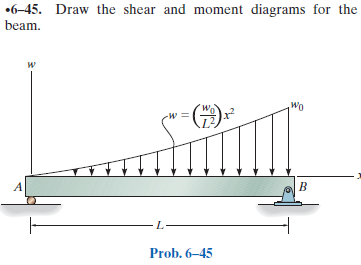

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-45P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-45P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
wo = sym('wo');
L = sym('L', 'positive');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', L);
b = b.add('distributed', 'force', -(wo/L^2)*x^2, [0 L]);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \frac{\mathrm{wo}\,x\,\left(L-x\right)\,\left(-4\,L^{4}-4\,L^{3}\,x+L^{2}\,x^{2}+L\,x^{3}+x^{4}\right)}{360\,\text{E}\,\text{I}\,L^{2}}$$

dy

$$dy(x) = -\frac{\mathrm{wo}\,\left(4\,L^{5}-15\,L^{3}\,x^{2}+6\,x^{5}\right)}{360\,\text{E}\,\text{I}\,L^{2}}$$

m

$$m(x) = \frac{\mathrm{wo}\,x\,\left(L-x\right)\,\left(L^{2}+L\,x+x^{2}\right)}{12\,L^{2}}$$

v

$$v(x) = \frac{\mathrm{wo}\,\left(L^{3}-4\,x^{3}\right)}{12\,L^{2}}$$

w

$$w(x) = -\frac{\mathrm{wo}\,x^{2}}{L^{2}}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & \frac{L\,\mathrm{wo}}{12}\\ \mathrm{Rb} & \frac{L\,\mathrm{wo}}{4} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

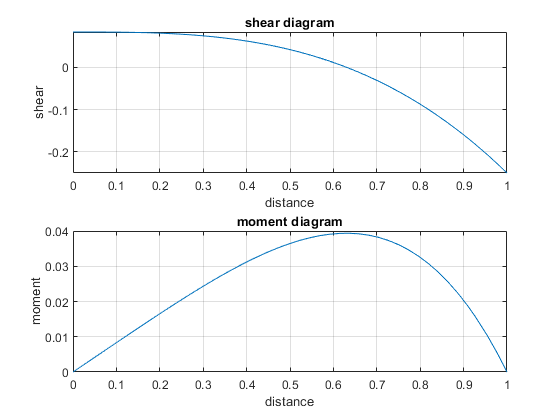

beam.shear_moment(m, v, [0 1], [wo L], 1);

# clean up

addvar(y);
new_assum = assumptions;